## Load Dataset

load('pixelgTruth.mat');
Dataset = pixelLabelImageDatastore(gTruth);
imds = imageDatastore(Dataset.Images);
labelims = Dataset.PixelLabelData;
classes = Dataset.ClassNames;
labelIDs = gTruth.LabelDefinitions.PixelLabelID;
pxds = pixelLabelDatastore(labelims,classes,labelIDs);
    

## Read data

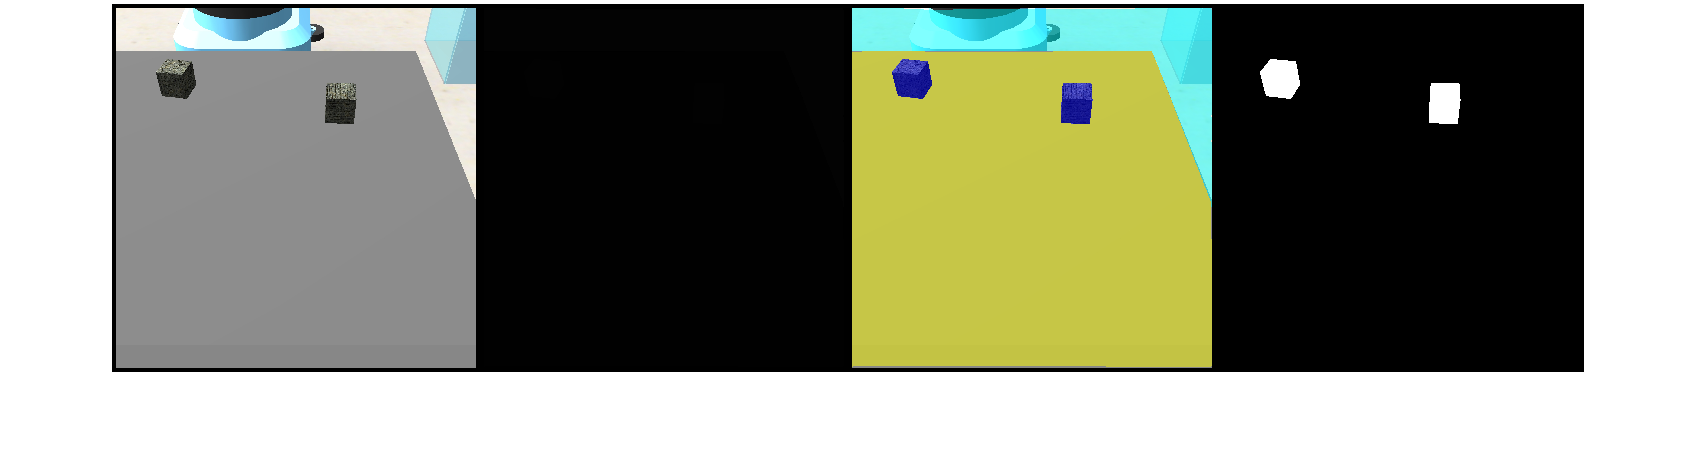

I = readimage(imds,97);
C = readimage(pxds,97);
P = uint8(C);
B = labeloverlay(I,C);
Mask = C == 'cube';
figure;
montage({I,P,B,Mask},'BorderSize',4,'Size',[1 4])

## Analyze Dataset statistics

tbl = countEachLabel(pxds)

tbl = 3×3 table
         Name         PixelCount    ImagePixelCount
    ______________    __________    _______________

    {'Belt'      }    337577624        415236096   
    {'cube'      }     10689458        415236096   
    {'Background'}     63370661        415236096   


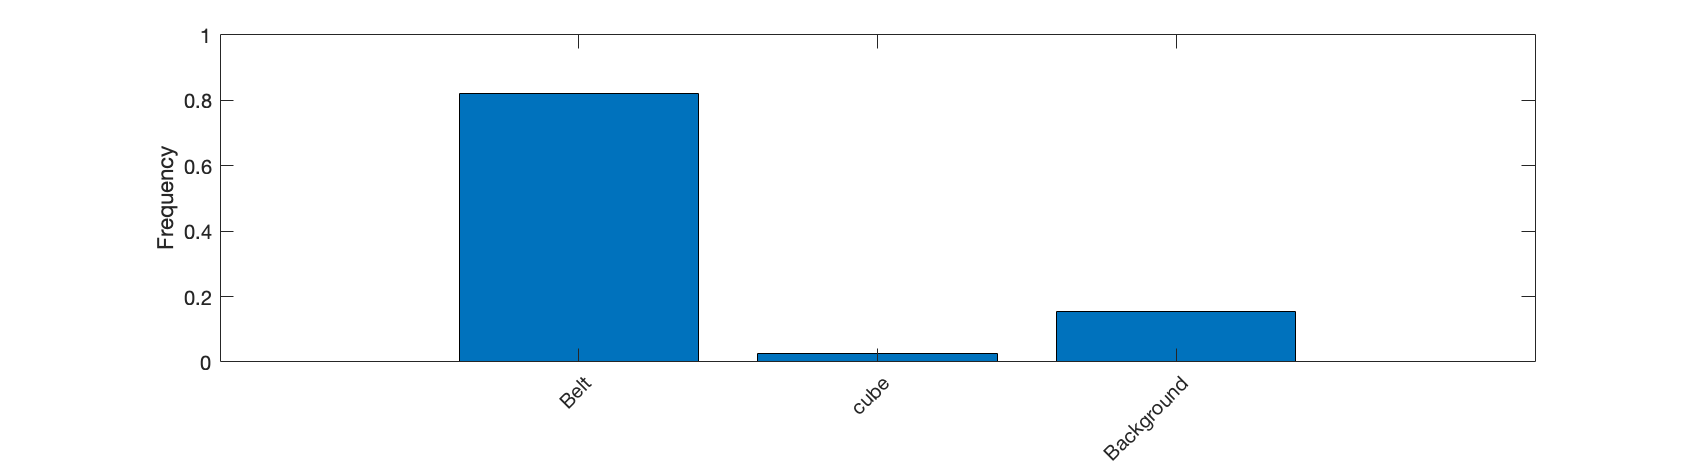

frequency = tbl.PixelCount/sum(tbl.PixelCount);
bar(1:numel(classes),frequency)
xticks(1:numel(classes)) 
xticklabels(tbl.Name)
xtickangle(45)
ylabel('Frequency')

## Prepare Datasets

[imdsTrain, imdsVal, imdsTest, pxdsTrain, pxdsVal, pxdsTest] = partitionData(Dataset,labelIDs);

## Create Network

inputSize = [256 256 3];
numClasses = numel(classes);
lgraph = deeplabv3plusLayers(inputSize,numClasses,"resnet50");

## Balance Classes 

imageFreq = tbl.PixelCount ./ tbl.ImagePixelCount;
classweights = median(imageFreq) ./ imageFreq

classweights =    0.187721746036106
   5.928332474855132
   1.000000000000000


pxLayer = pixelClassificationLayer("Name","labels","Classes",tbl.Name,"ClassWeights",classweights)

pxLayer =   PixelClassificationLayer with properties:

            Name: 'labels'
         Classes: [Belt    cube    Background]
    ClassWeights: [3×1 double]
      OutputSize: 'auto'

   Hyperparameters
    LossFunction: 'crossentropyex'


lgraph = replaceLayer(lgraph,"classification",pxLayer);

## Data augmentation

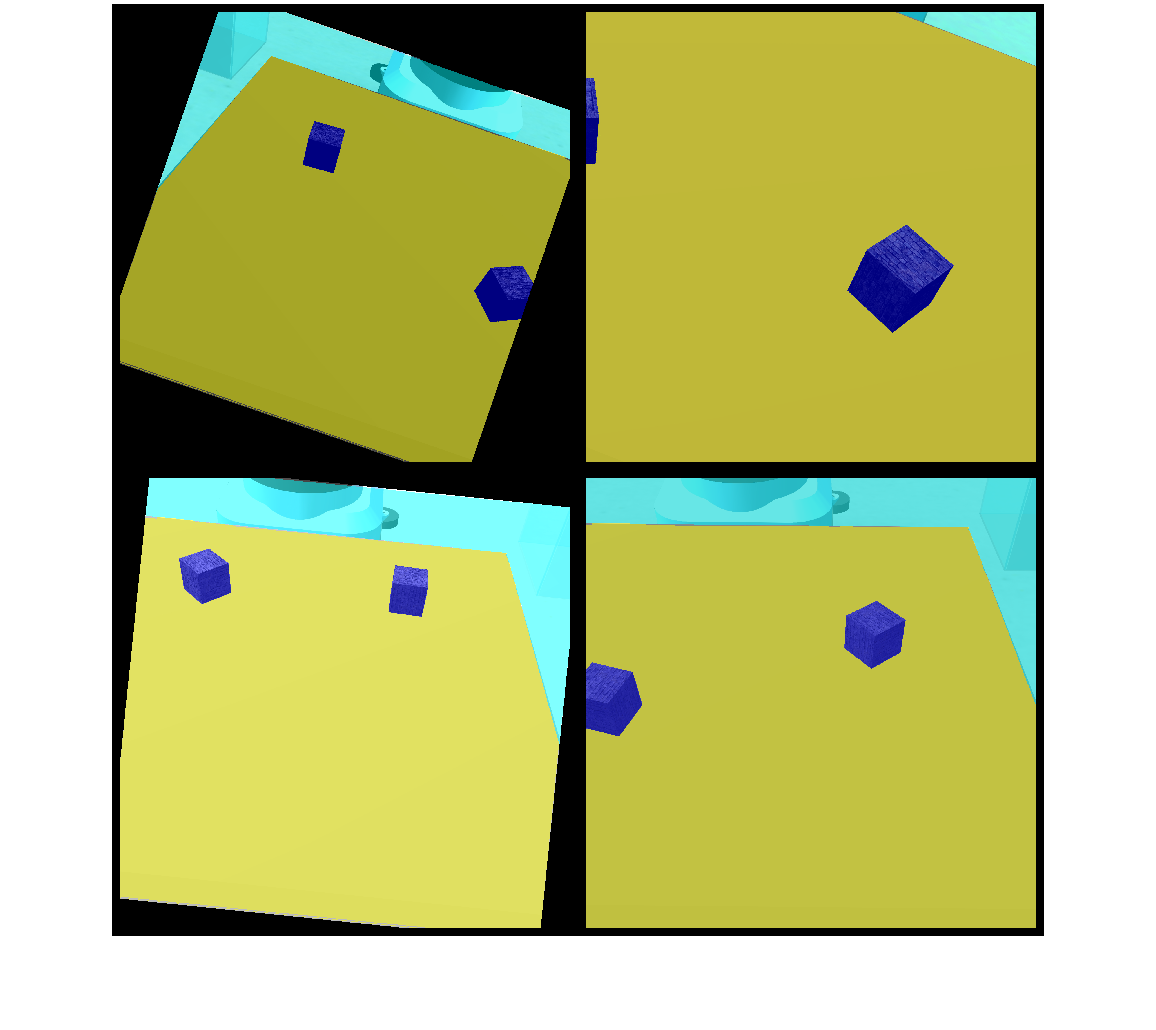

trainingData = combine(imdsTrain,pxdsTrain);
valData = combine(imdsVal,pxdsVal);
testData = combine(imdsTest,pxdsTest);
augmentedTrainingData = transform(trainingData,@jitterImageColorAndWarp);
rgb = cell(4,1);
for k = 1:4
    data = read(augmentedTrainingData);
    rgb{k} = labeloverlay(data{1,1},data{1,2});
end
montage(rgb,'BorderSize',8)

## Preprocess Dataset

PPtraining = transform(augmentedTrainingData,@(data)resizeImageandLabel(data,inputSize(1:2)));
PPval = transform(valData,@(data)resizeImageandLabel(data,inputSize(1:2)));
PPtest = transform(testData,@(data)resizeImageandLabel(data,inputSize(1:2)));

## Train Network

opts = trainingOptions("sgdm",...
                       'MaxEpochs',30,"MiniBatchSize",2,...
                       'ValidationData',PPval,...
                       'InitialLearnRate',1e-3,...
                       'L2Regularization',0.0005,...
                       'ValidationFrequency',10,...
                       "Shuffle","every-epoch",...
                       "Plots","training-progress",...
                       'ExecutionEnvironment',"auto",...
                       'VerboseFrequency',2);
DCNN = trainNetwork(PPtraining,lgraph,opts);

Training on single CPU.
Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:30 |       33.40% |       65.79% |       1.8058 |       0.8393 |          0.0010 |


|       1 |           2 |       00:00:44 |       61.21% |              |       0.8298 |              |          0.0010 |


|       1 |           4 |       00:00:52 |       78.50% |              |       0.5640 |              |          0.0010 |


|       1 |           6 |       00:00:59 |       83.13% |              |       0.5864 |              |          0.0010 |


|       1 |           8 |       00:01:05 |       90.90% |              |       0.3494 |              |          0.0010 |


|       1 |          10 |       00:01:16 |       93.91% |       91.23% |       0.2427 |       0.3719 |          0.0010 |


|       1 |          12 |       00:01:23 |       95.48% |              |       0.2042 |              |          0.0010 |


|       1 |          14 |       00:01:29 |       96.01% |              |       0.1515 |              |          0.0010 |


|       1 |          16 |       00:01:35 |       96.14% |              |       0.1141 |              |          0.0010 |


|       1 |          18 |       00:01:43 |       96.09% |              |       0.1310 |              |          0.0010 |


|       1 |          20 |       00:01:53 |       97.15% |       95.99% |       0.1509 |       0.1060 |          0.0010 |


|       1 |          22 |       00:01:59 |       95.74% |              |       0.0949 |              |          0.0010 |


|       1 |          24 |       00:02:05 |       96.11% |              |       0.0910 |              |          0.0010 |


|       1 |          26 |       00:02:12 |       96.82% |              |       0.0662 |              |          0.0010 |


|       1 |          28 |       00:02:19 |       94.69% |              |       0.1855 |              |          0.0010 |


|       1 |          30 |       00:02:29 |       95.80% |       96.01% |       0.0890 |       0.1380 |          0.0010 |


|       1 |          32 |       00:02:35 |       97.64% |              |       0.0950 |              |          0.0010 |


|       1 |          34 |       00:02:42 |       95.19% |              |       0.0812 |              |          0.0010 |


|       1 |          36 |       00:02:47 |       95.93% |              |       0.0742 |              |          0.0010 |


|       2 |          38 |       00:02:56 |       94.65% |              |       0.0948 |              |          0.0010 |


|       2 |          40 |       00:03:08 |       95.83% |       96.04% |       0.0795 |       0.0874 |          0.0010 |


|       2 |          42 |       00:03:15 |       95.93% |              |       0.0733 |              |          0.0010 |


|       2 |          44 |       00:03:23 |       97.69% |              |       0.0396 |              |          0.0010 |


|       2 |          46 |       00:03:34 |       97.31% |              |       0.0566 |              |          0.0010 |


|       2 |          48 |       00:03:40 |       98.05% |              |       0.0507 |              |          0.0010 |


|       2 |          50 |       00:03:51 |       96.94% |       96.81% |       0.0564 |       0.0739 |          0.0010 |


|       2 |          52 |       00:03:57 |       95.92% |              |       0.0546 |              |          0.0010 |


|       2 |          54 |       00:04:03 |       95.73% |              |       0.0641 |              |          0.0010 |


|       2 |          56 |       00:04:09 |       94.77% |              |       0.0640 |              |          0.0010 |


|       2 |          58 |       00:04:15 |       96.88% |              |       0.0620 |              |          0.0010 |


|       2 |          60 |       00:04:26 |       96.97% |       97.47% |       0.0452 |       0.0638 |          0.0010 |


|       2 |          62 |       00:04:32 |       93.19% |              |       0.1094 |              |          0.0010 |


|       2 |          64 |       00:04:38 |       97.53% |              |       0.0497 |              |          0.0010 |


|       2 |          66 |       00:04:44 |       98.05% |              |       0.0363 |              |          0.0010 |


|       2 |          68 |       00:04:50 |       97.82% |              |       0.0441 |              |          0.0010 |


|       2 |          70 |       00:05:00 |       98.32% |       98.33% |       0.0356 |       0.0606 |          0.0010 |


|       2 |          72 |       00:05:06 |       97.61% |              |       0.0409 |              |          0.0010 |


|       2 |          74 |       00:05:11 |       98.09% |              |       0.0459 |              |          0.0010 |


|       3 |          76 |       00:05:20 |       98.62% |              |       0.0434 |              |          0.0010 |


|       3 |          78 |       00:05:26 |       97.95% |              |       0.0323 |              |          0.0010 |


|       3 |          80 |       00:05:36 |       98.68% |       97.82% |       0.0394 |       0.0778 |          0.0010 |


|       3 |          82 |       00:05:43 |       97.37% |              |       0.0514 |              |          0.0010 |


|       3 |          84 |       00:05:52 |       97.63% |              |       0.0518 |              |          0.0010 |


|       3 |          86 |       00:06:04 |       98.64% |              |       0.0237 |              |          0.0010 |


|       3 |          88 |       00:06:12 |       98.13% |              |       0.0389 |              |          0.0010 |


|       3 |          90 |       00:06:26 |       98.31% |       98.58% |       0.0411 |       0.0467 |          0.0010 |


|       3 |          92 |       00:06:32 |       98.74% |              |       0.0318 |              |          0.0010 |


|       3 |          94 |       00:06:38 |       98.60% |              |       0.0253 |              |          0.0010 |


|       3 |          96 |       00:06:44 |       98.62% |              |       0.0322 |              |          0.0010 |


|       3 |          98 |       00:06:50 |       98.46% |              |       0.0303 |              |          0.0010 |


|       3 |         100 |       00:07:00 |       97.71% |       98.32% |       0.0446 |       0.0596 |          0.0010 |


|       3 |         102 |       00:07:06 |       98.85% |              |       0.0330 |              |          0.0010 |


|       3 |         104 |       00:07:12 |       98.68% |              |       0.0282 |              |          0.0010 |


|       3 |         106 |       00:07:19 |       98.65% |              |       0.0291 |              |          0.0010 |


|       3 |         108 |       00:07:25 |       98.63% |              |       0.0382 |              |          0.0010 |


|       3 |         110 |       00:07:34 |       98.76% |       98.25% |       0.0247 |       0.0592 |          0.0010 |


|       4 |         112 |       00:07:43 |       98.04% |              |       0.0407 |              |          0.0010 |


|       4 |         114 |       00:07:49 |       98.81% |              |       0.0222 |              |          0.0010 |


|       4 |         116 |       00:07:55 |       98.64% |              |       0.0298 |              |          0.0010 |


|       4 |         118 |       00:08:01 |       98.60% |              |       0.0308 |              |          0.0010 |


|       4 |         120 |       00:08:12 |       98.29% |       98.42% |       0.0352 |       0.0522 |          0.0010 |


|       4 |         122 |       00:08:18 |       98.66% |              |       0.0289 |              |          0.0010 |


|       4 |         124 |       00:08:24 |       98.45% |              |       0.0267 |              |          0.0010 |


|       4 |         126 |       00:08:31 |       98.83% |              |       0.0310 |              |          0.0010 |


|       4 |         128 |       00:08:37 |       98.41% |              |       0.0376 |              |          0.0010 |


|       4 |         130 |       00:08:47 |       98.84% |       98.92% |       0.0185 |       0.0440 |          0.0010 |


|       4 |         132 |       00:08:53 |       98.73% |              |       0.0403 |              |          0.0010 |


|       4 |         134 |       00:09:00 |       98.95% |              |       0.0265 |              |          0.0010 |


|       4 |         136 |       00:09:06 |       98.93% |              |       0.0241 |              |          0.0010 |


|       4 |         138 |       00:09:12 |       98.89% |              |       0.0311 |              |          0.0010 |


|       4 |         140 |       00:09:22 |       99.14% |       98.59% |       0.0234 |       0.0505 |          0.0010 |


|       4 |         142 |       00:09:28 |       98.88% |              |       0.0331 |              |          0.0010 |


|       4 |         144 |       00:09:34 |       98.60% |              |       0.0285 |              |          0.0010 |


|       4 |         146 |       00:09:41 |       98.92% |              |       0.0196 |              |          0.0010 |


|       4 |         148 |       00:09:45 |       99.16% |              |       0.0235 |              |          0.0010 |


|       5 |         150 |       00:09:59 |       98.69% |       99.11% |       0.0220 |       0.0345 |          0.0010 |


|       5 |         152 |       00:10:05 |       98.91% |              |       0.0225 |              |          0.0010 |


|       5 |         154 |       00:10:11 |       98.94% |              |       0.0213 |              |          0.0010 |


|       5 |         156 |       00:10:17 |       99.22% |              |       0.0201 |              |          0.0010 |


|       5 |         158 |       00:10:24 |       98.55% |              |       0.0293 |              |          0.0010 |


|       5 |         160 |       00:10:33 |       98.74% |       98.28% |       0.0342 |       0.0612 |          0.0010 |


|       5 |         162 |       00:10:40 |       99.19% |              |       0.0227 |              |          0.0010 |


|       5 |         164 |       00:10:46 |       98.03% |              |       0.0293 |              |          0.0010 |


|       5 |         166 |       00:10:52 |       98.73% |              |       0.0428 |              |          0.0010 |


|       5 |         168 |       00:10:58 |       98.83% |              |       0.0213 |              |          0.0010 |


|       5 |         170 |       00:11:08 |       98.95% |       99.34% |       0.0235 |       0.0309 |          0.0010 |


|       5 |         172 |       00:11:14 |       99.29% |              |       0.0217 |              |          0.0010 |


|       5 |         174 |       00:11:21 |       98.51% |              |       0.0327 |              |          0.0010 |


|       5 |         176 |       00:11:27 |       98.48% |              |       0.0308 |              |          0.0010 |


|       5 |         178 |       00:11:33 |       98.63% |              |       0.0228 |              |          0.0010 |


|       5 |         180 |       00:11:43 |       98.84% |       98.92% |       0.0244 |       0.0284 |          0.0010 |


|       5 |         182 |       00:11:49 |       98.77% |              |       0.0213 |              |          0.0010 |


|       5 |         184 |       00:11:54 |       98.86% |              |       0.0286 |              |          0.0010 |


|       6 |         186 |       00:12:03 |       99.01% |              |       0.0192 |              |          0.0010 |


|       6 |         188 |       00:12:09 |       98.84% |              |       0.0213 |              |          0.0010 |


|       6 |         190 |       00:12:19 |       97.54% |       99.10% |       0.0644 |       0.0330 |          0.0010 |


|       6 |         192 |       00:12:25 |       99.02% |              |       0.0174 |              |          0.0010 |


|       6 |         194 |       00:12:31 |       99.06% |              |       0.0215 |              |          0.0010 |


|       6 |         196 |       00:12:37 |       98.75% |              |       0.0199 |              |          0.0010 |


|       6 |         198 |       00:12:44 |       99.07% |              |       0.0194 |              |          0.0010 |


|       6 |         200 |       00:12:54 |       98.83% |       98.42% |       0.0255 |       0.0559 |          0.0010 |


|       6 |         202 |       00:13:00 |       98.75% |              |       0.0231 |              |          0.0010 |


|       6 |         204 |       00:13:06 |       99.01% |              |       0.0205 |              |          0.0010 |


|       6 |         206 |       00:13:19 |       99.20% |              |       0.0205 |              |          0.0010 |


|       6 |         208 |       00:13:25 |       99.07% |              |       0.0163 |              |          0.0010 |


|       6 |         210 |       00:13:35 |       99.11% |       99.31% |       0.0175 |       0.0229 |          0.0010 |


|       6 |         212 |       00:13:42 |       98.73% |              |       0.0220 |              |          0.0010 |


|       6 |         214 |       00:13:48 |       98.63% |              |       0.0214 |              |          0.0010 |


|       6 |         216 |       00:13:54 |       98.93% |              |       0.0222 |              |          0.0010 |


|       6 |         218 |       00:14:00 |       98.34% |              |       0.0311 |              |          0.0010 |


|       6 |         220 |       00:14:10 |       98.37% |       99.05% |       0.0261 |       0.0269 |          0.0010 |


|       6 |         222 |       00:14:14 |       98.83% |              |       0.0223 |              |          0.0010 |


|       7 |         224 |       00:14:24 |       99.33% |              |       0.0143 |              |          0.0010 |


|       7 |         226 |       00:14:30 |       99.44% |              |       0.0271 |              |          0.0010 |


|       7 |         228 |       00:14:36 |       99.29% |              |       0.0184 |              |          0.0010 |


|       7 |         230 |       00:14:47 |       98.49% |       98.89% |       0.0301 |       0.0378 |          0.0010 |


|       7 |         232 |       00:14:53 |       99.17% |              |       0.0235 |              |          0.0010 |


|       7 |         234 |       00:14:59 |       99.32% |              |       0.0157 |              |          0.0010 |


|       7 |         236 |       00:15:05 |       99.29% |              |       0.0172 |              |          0.0010 |


|       7 |         238 |       00:15:11 |       98.47% |              |       0.0530 |              |          0.0010 |


|       7 |         240 |       00:15:22 |       99.33% |       99.13% |       0.0162 |       0.0314 |          0.0010 |


|       7 |         242 |       00:15:28 |       98.79% |              |       0.0310 |              |          0.0010 |


|       7 |         244 |       00:15:34 |       98.87% |              |       0.0189 |              |          0.0010 |


|       7 |         246 |       00:15:40 |       99.20% |              |       0.0330 |              |          0.0010 |


|       7 |         248 |       00:15:46 |       99.38% |              |       0.0147 |              |          0.0010 |


|       7 |         250 |       00:15:57 |       98.32% |       98.81% |       0.0328 |       0.0356 |          0.0010 |


|       7 |         252 |       00:16:03 |       98.42% |              |       0.0289 |              |          0.0010 |


|       7 |         254 |       00:16:09 |       98.73% |              |       0.0198 |              |          0.0010 |


|       7 |         256 |       00:16:17 |       98.67% |              |       0.0348 |              |          0.0010 |


|       7 |         258 |       00:16:22 |       99.03% |              |       0.0186 |              |          0.0010 |


|       8 |         260 |       00:16:35 |       98.94% |       99.16% |       0.0208 |       0.0344 |          0.0010 |


|       8 |         262 |       00:16:41 |       99.33% |              |       0.0143 |              |          0.0010 |


|       8 |         264 |       00:16:47 |       98.69% |              |       0.0203 |              |          0.0010 |


|       8 |         266 |       00:16:53 |       99.41% |              |       0.0155 |              |          0.0010 |


|       8 |         268 |       00:16:59 |       99.39% |              |       0.0220 |              |          0.0010 |


|       8 |         270 |       00:17:09 |       99.07% |       98.97% |       0.0182 |       0.0367 |          0.0010 |


|       8 |         272 |       00:17:16 |       98.89% |              |       0.0189 |              |          0.0010 |


|       8 |         274 |       00:17:22 |       99.29% |              |       0.0162 |              |          0.0010 |


|       8 |         276 |       00:17:29 |       98.64% |              |       0.0200 |              |          0.0010 |


|       8 |         278 |       00:17:35 |       97.95% |              |       0.0274 |              |          0.0010 |


|       8 |         280 |       00:17:45 |       99.33% |       99.22% |       0.0166 |       0.0240 |          0.0010 |


|       8 |         282 |       00:17:51 |       99.12% |              |       0.0146 |              |          0.0010 |


|       8 |         284 |       00:17:58 |       99.02% |              |       0.0223 |              |          0.0010 |


|       8 |         286 |       00:18:04 |       98.94% |              |       0.0188 |              |          0.0010 |


|       8 |         288 |       00:18:10 |       99.26% |              |       0.0161 |              |          0.0010 |


|       8 |         290 |       00:18:20 |       99.42% |       99.06% |       0.0128 |       0.0350 |          0.0010 |


|       8 |         292 |       00:18:27 |       98.80% |              |       0.0234 |              |          0.0010 |


|       8 |         294 |       00:18:33 |       99.14% |              |       0.0210 |              |          0.0010 |


|       8 |         296 |       00:18:37 |       99.14% |              |       0.0185 |              |          0.0010 |


|       9 |         298 |       00:18:46 |       99.45% |              |       0.0164 |              |          0.0010 |


|       9 |         300 |       00:18:56 |       98.54% |       99.22% |       0.0290 |       0.0293 |          0.0010 |


|       9 |         302 |       00:19:03 |       99.16% |              |       0.0188 |              |          0.0010 |


|       9 |         304 |       00:19:09 |       98.96% |              |       0.0189 |              |          0.0010 |


|       9 |         306 |       00:19:15 |       98.80% |              |       0.0207 |              |          0.0010 |


|       9 |         308 |       00:19:21 |       99.35% |              |       0.0141 |              |          0.0010 |


|       9 |         310 |       00:19:31 |       98.65% |       99.22% |       0.0229 |       0.0300 |          0.0010 |


|       9 |         312 |       00:19:37 |       99.42% |              |       0.0160 |              |          0.0010 |


|       9 |         314 |       00:19:44 |       97.85% |              |       0.0702 |              |          0.0010 |


|       9 |         316 |       00:19:50 |       99.32% |              |       0.0152 |              |          0.0010 |


|       9 |         318 |       00:19:56 |       99.51% |              |       0.0122 |              |          0.0010 |


|       9 |         320 |       00:20:06 |       99.31% |       99.21% |       0.0147 |       0.0284 |          0.0010 |


|       9 |         322 |       00:20:12 |       98.81% |              |       0.0166 |              |          0.0010 |


|       9 |         324 |       00:20:18 |       99.05% |              |       0.0148 |              |          0.0010 |


|       9 |         326 |       00:20:24 |       98.90% |              |       0.0189 |              |          0.0010 |


|       9 |         328 |       00:20:31 |       98.76% |              |       0.0178 |              |          0.0010 |


|       9 |         330 |       00:20:41 |       98.89% |       99.12% |       0.0160 |       0.0287 |          0.0010 |


|       9 |         332 |       00:20:46 |       99.48% |              |       0.0127 |              |          0.0010 |


|      10 |         334 |       00:20:55 |       99.39% |              |       0.0148 |              |          0.0010 |


|      10 |         336 |       00:21:01 |       99.12% |              |       0.0152 |              |          0.0010 |


|      10 |         338 |       00:21:07 |       99.29% |              |       0.0188 |              |          0.0010 |


|      10 |         340 |       00:21:18 |       98.83% |       99.21% |       0.0220 |       0.0241 |          0.0010 |


|      10 |         342 |       00:21:24 |       98.64% |              |       0.0252 |              |          0.0010 |


|      10 |         344 |       00:21:30 |       99.11% |              |       0.0154 |              |          0.0010 |


|      10 |         346 |       00:21:36 |       99.39% |              |       0.0238 |              |          0.0010 |


|      10 |         348 |       00:21:43 |       99.46% |              |       0.0146 |              |          0.0010 |


|      10 |         350 |       00:21:53 |       99.39% |       99.22% |       0.0102 |       0.0238 |          0.0010 |


|      10 |         352 |       00:21:59 |       98.61% |              |       0.0290 |              |          0.0010 |


|      10 |         354 |       00:22:05 |       99.02% |              |       0.0196 |              |          0.0010 |


|      10 |         356 |       00:22:11 |       99.28% |              |       0.0140 |              |          0.0010 |


|      10 |         358 |       00:22:18 |       99.06% |              |       0.0167 |              |          0.0010 |


|      10 |         360 |       00:22:28 |       99.33% |       99.31% |       0.0182 |       0.0237 |          0.0010 |


|      10 |         362 |       00:22:34 |       99.22% |              |       0.0141 |              |          0.0010 |


|      10 |         364 |       00:22:43 |       99.25% |              |       0.0184 |              |          0.0010 |


|      10 |         366 |       00:22:49 |       99.29% |              |       0.0134 |              |          0.0010 |


|      10 |         368 |       00:22:55 |       98.32% |              |       0.0245 |              |          0.0010 |


|      10 |         370 |       00:23:06 |       99.22% |       99.27% |       0.0162 |       0.0239 |          0.0010 |


|      11 |         372 |       00:23:16 |       99.24% |              |       0.0150 |              |          0.0010 |


|      11 |         374 |       00:23:22 |       99.43% |              |       0.0122 |              |          0.0010 |


|      11 |         376 |       00:23:28 |       99.47% |              |       0.0124 |              |          0.0010 |


|      11 |         378 |       00:23:34 |       99.37% |              |       0.0125 |              |          0.0010 |


|      11 |         380 |       00:23:43 |       99.36% |       99.25% |       0.0132 |       0.0296 |          0.0010 |


|      11 |         382 |       00:23:49 |       98.85% |              |       0.0168 |              |          0.0010 |


|      11 |         384 |       00:23:55 |       99.32% |              |       0.0208 |              |          0.0010 |


|      11 |         386 |       00:24:01 |       99.54% |              |       0.0118 |              |          0.0010 |


|      11 |         388 |       00:24:07 |       99.39% |              |       0.0120 |              |          0.0010 |


|      11 |         390 |       00:24:17 |       99.27% |       99.29% |       0.0154 |       0.0217 |          0.0010 |


|      11 |         392 |       00:24:22 |       99.33% |              |       0.0142 |              |          0.0010 |


|      11 |         394 |       00:24:28 |       99.42% |              |       0.0119 |              |          0.0010 |


|      11 |         396 |       00:24:34 |       99.20% |              |       0.0177 |              |          0.0010 |


|      11 |         398 |       00:24:40 |       99.47% |              |       0.0100 |              |          0.0010 |


|      11 |         400 |       00:24:50 |       99.45% |       99.18% |       0.0106 |       0.0310 |          0.0010 |


|      11 |         402 |       00:24:56 |       99.00% |              |       0.0236 |              |          0.0010 |


|      11 |         404 |       00:25:02 |       99.62% |              |       0.0116 |              |          0.0010 |


|      12 |         408 |       00:26:23 |       99.28% |              |       0.0138 |              |          0.0010 |


|      12 |         410 |       00:26:35 |       99.36% |       99.27% |       0.0115 |       0.0238 |          0.0010 |


|      12 |         412 |       00:26:41 |       98.79% |              |       0.0252 |              |          0.0010 |


|      12 |         414 |       00:27:15 |       99.22% |              |       0.0124 |              |          0.0010 |


|      12 |         416 |       00:27:21 |       98.98% |              |       0.0206 |              |          0.0010 |


|      12 |         418 |       00:27:26 |       99.38% |              |       0.0140 |              |          0.0010 |


|      12 |         420 |       00:27:36 |       99.46% |       99.34% |       0.0126 |       0.0233 |          0.0010 |


|      12 |         422 |       00:27:43 |       99.34% |              |       0.0147 |              |          0.0010 |


|      12 |         424 |       00:28:14 |       99.65% |              |       0.0099 |              |          0.0010 |


|      12 |         426 |       00:28:31 |       99.55% |              |       0.0116 |              |          0.0010 |


|      12 |         428 |       00:28:42 |       99.31% |              |       0.0195 |              |          0.0010 |


|      12 |         430 |       00:28:55 |       99.44% |       99.18% |       0.0119 |       0.0290 |          0.0010 |


|      12 |         432 |       00:29:02 |       99.36% |              |       0.0134 |              |          0.0010 |


|      12 |         434 |       00:29:09 |       99.33% |              |       0.0134 |              |          0.0010 |


|      12 |         436 |       00:29:15 |       99.37% |              |       0.0116 |              |          0.0010 |


|      12 |         438 |       00:29:22 |       99.32% |              |       0.0159 |              |          0.0010 |


|      12 |         440 |       00:29:35 |       99.34% |       99.33% |       0.0125 |       0.0217 |          0.0010 |


|      12 |         442 |       00:29:42 |       99.39% |              |       0.0128 |              |          0.0010 |


|      12 |         444 |       00:29:47 |       98.50% |              |       0.0224 |              |          0.0010 |


|      13 |         446 |       00:29:58 |       99.55% |              |       0.0107 |              |          0.0010 |


|      13 |         448 |       00:30:05 |       98.90% |              |       0.0244 |              |          0.0010 |


|      13 |         450 |       00:30:15 |       99.25% |       99.41% |       0.0123 |       0.0211 |          0.0010 |


|      13 |         452 |       00:30:22 |       99.50% |              |       0.0140 |              |          0.0010 |


|      13 |         454 |       00:30:28 |       99.39% |              |       0.0133 |              |          0.0010 |


|      13 |         456 |       00:30:35 |       99.32% |              |       0.0110 |              |          0.0010 |


|      13 |         458 |       00:30:41 |       99.32% |              |       0.0111 |              |          0.0010 |


|      13 |         460 |       00:30:51 |       99.34% |       99.23% |       0.0163 |       0.0272 |          0.0010 |


|      13 |         462 |       00:30:58 |       99.25% |              |       0.0133 |              |          0.0010 |


|      13 |         464 |       00:31:04 |       99.47% |              |       0.0115 |              |          0.0010 |


|      13 |         466 |       00:31:11 |       99.36% |              |       0.0139 |              |          0.0010 |


|      13 |         468 |       00:31:17 |       99.39% |              |       0.0110 |              |          0.0010 |


|      13 |         470 |       00:31:28 |       99.37% |       99.40% |       0.0113 |       0.0201 |          0.0010 |


|      13 |         472 |       00:31:34 |       99.31% |              |       0.0148 |              |          0.0010 |


|      13 |         474 |       00:31:40 |       98.91% |              |       0.0156 |              |          0.0010 |


|      13 |         476 |       00:31:47 |       99.41% |              |       0.0142 |              |          0.0010 |


|      13 |         478 |       00:31:53 |       99.21% |              |       0.0141 |              |          0.0010 |


|      13 |         480 |       00:32:03 |       99.27% |       99.28% |       0.0125 |       0.0267 |          0.0010 |


|      14 |         482 |       00:32:11 |       99.03% |              |       0.0163 |              |          0.0010 |


|      14 |         484 |       00:32:18 |       99.49% |              |       0.0136 |              |          0.0010 |


|      14 |         486 |       00:32:24 |       99.49% |              |       0.0149 |              |          0.0010 |


|      14 |         488 |       00:32:31 |       99.32% |              |       0.0152 |              |          0.0010 |


|      14 |         490 |       00:32:41 |       99.45% |       99.32% |       0.0109 |       0.0237 |          0.0010 |


|      14 |         492 |       00:32:48 |       99.21% |              |       0.0179 |              |          0.0010 |


|      14 |         494 |       00:32:54 |       99.32% |              |       0.0133 |              |          0.0010 |


|      14 |         496 |       00:33:00 |       99.37% |              |       0.0121 |              |          0.0010 |


|      14 |         498 |       00:33:07 |       99.25% |              |       0.0127 |              |          0.0010 |


|      14 |         500 |       00:33:19 |       99.49% |       99.31% |       0.0168 |       0.0207 |          0.0010 |


|      14 |         502 |       00:33:27 |       99.46% |              |       0.0101 |              |          0.0010 |


|      14 |         504 |       00:33:33 |       98.94% |              |       0.0180 |              |          0.0010 |


|      14 |         506 |       00:33:40 |       99.44% |              |       0.0194 |              |          0.0010 |


|      14 |         508 |       00:33:46 |       99.37% |              |       0.0159 |              |          0.0010 |


|      14 |         510 |       00:33:56 |       99.33% |       99.33% |       0.0130 |       0.0227 |          0.0010 |


|      14 |         512 |       00:34:03 |       99.39% |              |       0.0127 |              |          0.0010 |


|      14 |         514 |       00:34:09 |       98.92% |              |       0.0227 |              |          0.0010 |


|      14 |         516 |       00:34:15 |       99.03% |              |       0.0203 |              |          0.0010 |


|      14 |         518 |       00:34:20 |       99.42% |              |       0.0120 |              |          0.0010 |


|      15 |         520 |       00:34:33 |       99.16% |       99.34% |       0.0253 |       0.0254 |          0.0010 |


|      15 |         522 |       00:34:40 |       99.52% |              |       0.0129 |              |          0.0010 |


|      15 |         524 |       00:34:46 |       99.34% |              |       0.0128 |              |          0.0010 |


|      15 |         526 |       00:34:52 |       99.41% |              |       0.0121 |              |          0.0010 |


|      15 |         528 |       00:34:59 |       99.44% |              |       0.0194 |              |          0.0010 |


|      15 |         530 |       00:35:09 |       99.12% |       99.33% |       0.0161 |       0.0228 |          0.0010 |


|      15 |         532 |       00:35:16 |       99.16% |              |       0.0126 |              |          0.0010 |


|      15 |         534 |       00:35:22 |       98.95% |              |       0.0180 |              |          0.0010 |


|      15 |         536 |       00:35:28 |       99.25% |              |       0.0120 |              |          0.0010 |


|      15 |         538 |       00:35:35 |       99.38% |              |       0.0156 |              |          0.0010 |


|      15 |         540 |       00:35:45 |       99.32% |       99.45% |       0.0126 |       0.0201 |          0.0010 |


|      15 |         542 |       00:35:51 |       99.38% |              |       0.0123 |              |          0.0010 |


|      15 |         544 |       00:35:58 |       99.40% |              |       0.0101 |              |          0.0010 |


|      15 |         546 |       00:36:04 |       99.07% |              |       0.0143 |              |          0.0010 |


|      15 |         548 |       00:36:10 |       99.46% |              |       0.0111 |              |          0.0010 |


|      15 |         550 |       00:36:24 |       99.37% |       99.18% |       0.0120 |       0.0271 |          0.0010 |


|      15 |         552 |       00:36:30 |       99.30% |              |       0.0130 |              |          0.0010 |


|      15 |         554 |       00:36:35 |       99.02% |              |       0.0174 |              |          0.0010 |


|      16 |         556 |       00:36:44 |       99.27% |              |       0.0113 |              |          0.0010 |


|      16 |         558 |       00:36:51 |       99.41% |              |       0.0145 |              |          0.0010 |


|      16 |         560 |       00:37:01 |       99.60% |       99.47% |       0.0107 |       0.0165 |          0.0010 |


|      16 |         562 |       00:37:07 |       99.12% |              |       0.0151 |              |          0.0010 |


|      16 |         564 |       00:37:14 |       99.20% |              |       0.0130 |              |          0.0010 |


|      16 |         566 |       00:37:20 |       99.05% |              |       0.0163 |              |          0.0010 |


|      16 |         568 |       00:37:27 |       99.22% |              |       0.0165 |              |          0.0010 |


|      16 |         570 |       00:37:37 |       99.43% |       99.35% |       0.0134 |       0.0232 |          0.0010 |


|      16 |         572 |       00:37:43 |       99.29% |              |       0.0126 |              |          0.0010 |


|      16 |         574 |       00:37:50 |       98.92% |              |       0.0180 |              |          0.0010 |


|      16 |         576 |       00:37:56 |       99.44% |              |       0.0109 |              |          0.0010 |


|      16 |         578 |       00:38:03 |       99.38% |              |       0.0114 |              |          0.0010 |


|      16 |         580 |       00:38:13 |       99.38% |       99.36% |       0.0122 |       0.0221 |          0.0010 |


|      16 |         582 |       00:38:20 |       99.46% |              |       0.0158 |              |          0.0010 |


|      16 |         584 |       00:38:26 |       99.49% |              |       0.0127 |              |          0.0010 |


|      16 |         586 |       00:38:33 |       99.32% |              |       0.0146 |              |          0.0010 |


|      16 |         588 |       00:38:39 |       99.30% |              |       0.0132 |              |          0.0010 |


|      16 |         590 |       00:38:52 |       99.40% |       99.38% |       0.0115 |       0.0230 |          0.0010 |


|      16 |         592 |       00:38:57 |       99.55% |              |       0.0119 |              |          0.0010 |


|      17 |         594 |       00:39:07 |       99.24% |              |       0.0146 |              |          0.0010 |


|      17 |         596 |       00:39:14 |       99.49% |              |       0.0093 |              |          0.0010 |


|      17 |         598 |       00:39:20 |       99.01% |              |       0.0164 |              |          0.0010 |


|      17 |         600 |       00:39:31 |       99.51% |       99.37% |       0.0095 |       0.0236 |          0.0010 |


|      17 |         602 |       00:39:37 |       99.38% |              |       0.0118 |              |          0.0010 |


|      17 |         604 |       00:39:44 |       99.45% |              |       0.0148 |              |          0.0010 |


|      17 |         606 |       00:39:50 |       99.48% |              |       0.0126 |              |          0.0010 |


|      17 |         608 |       00:39:57 |       99.54% |              |       0.0116 |              |          0.0010 |


|      17 |         610 |       00:40:07 |       99.53% |       99.40% |       0.0098 |       0.0234 |          0.0010 |


|      17 |         612 |       00:40:14 |       99.34% |              |       0.0124 |              |          0.0010 |


|      17 |         614 |       00:40:20 |       99.60% |              |       0.0105 |              |          0.0010 |


|      17 |         616 |       00:40:26 |       99.24% |              |       0.0163 |              |          0.0010 |


|      17 |         618 |       00:40:33 |       99.19% |              |       0.0158 |              |          0.0010 |


|      17 |         620 |       00:40:43 |       99.37% |       99.49% |       0.0204 |       0.0177 |          0.0010 |


|      17 |         622 |       00:40:50 |       99.25% |              |       0.0145 |              |          0.0010 |


|      17 |         624 |       00:40:56 |       99.48% |              |       0.0116 |              |          0.0010 |


|      17 |         626 |       00:41:03 |       99.24% |              |       0.0153 |              |          0.0010 |


|      17 |         628 |       00:41:08 |       99.32% |              |       0.0121 |              |          0.0010 |


|      18 |         630 |       00:41:21 |       99.18% |       99.40% |       0.0115 |       0.0199 |          0.0010 |


|      18 |         632 |       00:41:27 |       98.65% |              |       0.0307 |              |          0.0010 |


|      18 |         634 |       00:41:34 |       99.37% |              |       0.0114 |              |          0.0010 |


|      18 |         636 |       00:41:40 |       99.62% |              |       0.0098 |              |          0.0010 |


|      18 |         638 |       00:41:47 |       99.45% |              |       0.0165 |              |          0.0010 |


|      18 |         640 |       00:41:58 |       99.29% |       99.40% |       0.0145 |       0.0208 |          0.0010 |


|      18 |         642 |       00:42:04 |       99.31% |              |       0.0151 |              |          0.0010 |


|      18 |         644 |       00:42:11 |       99.45% |              |       0.0116 |              |          0.0010 |


|      18 |         646 |       00:42:17 |       99.31% |              |       0.0116 |              |          0.0010 |


|      18 |         648 |       00:42:23 |       99.44% |              |       0.0137 |              |          0.0010 |


|      18 |         650 |       00:42:34 |       99.38% |       99.40% |       0.0114 |       0.0187 |          0.0010 |


|      18 |         652 |       00:42:40 |       99.34% |              |       0.0145 |              |          0.0010 |


|      18 |         654 |       00:42:47 |       99.26% |              |       0.0112 |              |          0.0010 |


|      18 |         656 |       00:42:53 |       99.10% |              |       0.0133 |              |          0.0010 |


|      18 |         658 |       00:43:00 |       99.47% |              |       0.0159 |              |          0.0010 |


|      18 |         660 |       00:43:10 |       99.20% |       99.44% |       0.0146 |       0.0209 |          0.0010 |


|      18 |         662 |       00:43:17 |       99.63% |              |       0.0087 |              |          0.0010 |


|      18 |         664 |       00:43:24 |       99.64% |              |       0.0093 |              |          0.0010 |


|      18 |         666 |       00:43:28 |       99.12% |              |       0.0133 |              |          0.0010 |


|      19 |         668 |       00:43:38 |       99.35% |              |       0.0113 |              |          0.0010 |


|      19 |         670 |       00:43:49 |       99.33% |       99.46% |       0.0184 |       0.0205 |          0.0010 |


|      19 |         672 |       00:43:55 |       99.44% |              |       0.0121 |              |          0.0010 |


|      19 |         674 |       00:44:02 |       99.11% |              |       0.0152 |              |          0.0010 |


|      19 |         676 |       00:44:08 |       99.48% |              |       0.0147 |              |          0.0010 |


|      19 |         678 |       00:44:14 |       99.34% |              |       0.0141 |              |          0.0010 |


|      19 |         680 |       00:44:23 |       99.29% |       99.41% |       0.0113 |       0.0184 |          0.0010 |


|      19 |         682 |       00:44:29 |       99.19% |              |       0.0122 |              |          0.0010 |


|      19 |         684 |       00:44:35 |       99.36% |              |       0.0112 |              |          0.0010 |


|      19 |         686 |       00:44:41 |       99.08% |              |       0.0126 |              |          0.0010 |


|      19 |         688 |       00:44:46 |       99.37% |              |       0.0100 |              |          0.0010 |


|      19 |         690 |       00:44:56 |       99.41% |       99.57% |       0.0100 |       0.0169 |          0.0010 |


|      19 |         692 |       00:45:02 |       99.28% |              |       0.0123 |              |          0.0010 |


|      19 |         694 |       00:45:08 |       99.48% |              |       0.0101 |              |          0.0010 |


|      19 |         696 |       00:45:14 |       99.39% |              |       0.0157 |              |          0.0010 |


|      19 |         698 |       00:45:20 |       99.52% |              |       0.0081 |              |          0.0010 |


|      19 |         700 |       00:45:29 |       99.27% |       99.43% |       0.0113 |       0.0186 |          0.0010 |


|      19 |         702 |       00:45:34 |       99.32% |              |       0.0102 |              |          0.0010 |


|      20 |         704 |       00:45:42 |       99.13% |              |       0.0135 |              |          0.0010 |


|      20 |         706 |       00:45:47 |       99.33% |              |       0.0118 |              |          0.0010 |


|      20 |         708 |       00:45:53 |       99.30% |              |       0.0106 |              |          0.0010 |


|      20 |         710 |       00:46:03 |       99.49% |       99.47% |       0.0124 |       0.0202 |          0.0010 |


|      20 |         712 |       00:46:09 |       99.28% |              |       0.0129 |              |          0.0010 |


|      20 |         714 |       00:46:15 |       99.44% |              |       0.0115 |              |          0.0010 |


|      20 |         716 |       00:46:21 |       99.53% |              |       0.0096 |              |          0.0010 |


|      20 |         718 |       00:46:27 |       99.43% |              |       0.0109 |              |          0.0010 |


|      20 |         720 |       00:46:36 |       99.48% |       99.48% |       0.0097 |       0.0182 |          0.0010 |


|      20 |         722 |       00:46:42 |       99.49% |              |       0.0093 |              |          0.0010 |


|      20 |         724 |       00:46:48 |       99.66% |              |       0.0111 |              |          0.0010 |


|      20 |         726 |       00:46:54 |       99.47% |              |       0.0103 |              |          0.0010 |


|      20 |         728 |       00:47:00 |       99.66% |              |       0.0088 |              |          0.0010 |


|      20 |         730 |       00:47:09 |       99.61% |       99.52% |       0.0103 |       0.0186 |          0.0010 |


|      20 |         732 |       00:47:15 |       99.55% |              |       0.0109 |              |          0.0010 |


|      20 |         734 |       00:47:21 |       99.53% |              |       0.0087 |              |          0.0010 |


|      20 |         736 |       00:47:27 |       99.62% |              |       0.0090 |              |          0.0010 |


|      20 |         738 |       00:47:32 |       99.51% |              |       0.0088 |              |          0.0010 |


|      20 |         740 |       00:47:40 |       99.53% |       99.47% |       0.0106 |       0.0183 |          0.0010 |


|      21 |         742 |       00:47:49 |       99.60% |              |       0.0083 |              |          0.0010 |


|      21 |         744 |       00:47:55 |       99.32% |              |       0.0109 |              |          0.0010 |


|      21 |         746 |       00:48:01 |       99.29% |              |       0.0174 |              |          0.0010 |


|      21 |         748 |       00:48:06 |       99.16% |              |       0.0135 |              |          0.0010 |


|      21 |         750 |       00:48:16 |       99.30% |       99.49% |       0.0119 |       0.0181 |          0.0010 |


|      21 |         752 |       00:48:22 |       99.52% |              |       0.0085 |              |          0.0010 |


|      21 |         754 |       00:48:28 |       99.45% |              |       0.0111 |              |          0.0010 |


|      21 |         756 |       00:48:33 |       99.61% |              |       0.0087 |              |          0.0010 |


|      21 |         758 |       00:48:39 |       99.48% |              |       0.0093 |              |          0.0010 |


|      21 |         760 |       00:48:49 |       99.51% |       99.41% |       0.0155 |       0.0193 |          0.0010 |


|      21 |         762 |       00:48:55 |       99.49% |              |       0.0077 |              |          0.0010 |


|      21 |         764 |       00:49:00 |       99.53% |              |       0.0085 |              |          0.0010 |


|      21 |         766 |       00:49:06 |       99.64% |              |       0.0085 |              |          0.0010 |


|      21 |         768 |       00:49:12 |       99.35% |              |       0.0130 |              |          0.0010 |


|      21 |         770 |       00:49:23 |       99.41% |       99.47% |       0.0114 |       0.0184 |          0.0010 |


|      21 |         772 |       00:49:41 |       99.56% |              |       0.0107 |              |          0.0010 |


|      21 |         774 |       00:50:16 |       99.46% |              |       0.0140 |              |          0.0010 |


|      21 |         776 |       00:50:22 |       99.40% |              |       0.0122 |              |          0.0010 |


|      22 |         778 |       00:50:33 |       99.42% |              |       0.0115 |              |          0.0010 |


|      22 |         780 |       00:50:43 |       99.31% |       99.46% |       0.0106 |       0.0190 |          0.0010 |


|      22 |         782 |       00:51:08 |       99.44% |              |       0.0106 |              |          0.0010 |


|      22 |         784 |       00:51:15 |       99.46% |              |       0.0097 |              |          0.0010 |


|      22 |         812 |       00:54:40 |       99.37% |              |       0.0112 |              |          0.0010 |


|      22 |         814 |       00:54:47 |       99.49% |              |       0.0179 |              |          0.0010 |


|      23 |         816 |       00:55:03 |       99.49% |              |       0.0092 |              |          0.0010 |


|      23 |         818 |       00:55:12 |       99.40% |              |       0.0118 |              |          0.0010 |


|      23 |         820 |       00:55:27 |       98.81% |       99.55% |       0.0330 |       0.0150 |          0.0010 |


|      23 |         822 |       00:55:38 |       99.47% |              |       0.0094 |              |          0.0010 |


|      23 |         824 |       00:55:48 |       99.29% |              |       0.0120 |              |          0.0010 |


|      23 |         826 |       00:55:58 |       99.33% |              |       0.0125 |              |          0.0010 |


|      23 |         828 |       00:56:07 |       99.24% |              |       0.0196 |              |          0.0010 |


|      23 |         830 |       00:56:25 |       99.56% |       99.51% |       0.0108 |       0.0166 |          0.0010 |


|      23 |         832 |       00:56:36 |       99.53% |              |       0.0080 |              |          0.0010 |


|      23 |         834 |       00:56:46 |       99.19% |              |       0.0133 |              |          0.0010 |


|      23 |         836 |       00:56:56 |       99.29% |              |       0.0107 |              |          0.0010 |


|      23 |         838 |       00:57:04 |       99.50% |              |       0.0084 |              |          0.0010 |


|      23 |         840 |       00:57:20 |       99.17% |       99.41% |       0.0132 |       0.0183 |          0.0010 |


|      23 |         842 |       00:57:30 |       99.45% |              |       0.0120 |              |          0.0010 |


|      23 |         844 |       00:57:40 |       99.41% |              |       0.0097 |              |          0.0010 |


|      23 |         846 |       00:57:50 |       99.24% |              |       0.0109 |              |          0.0010 |


|      23 |         848 |       00:57:59 |       99.53% |              |       0.0118 |              |          0.0010 |


|      23 |         850 |       00:58:14 |       99.15% |       99.62% |       0.0122 |       0.0150 |          0.0010 |


|      24 |         852 |       00:58:29 |       99.42% |              |       0.0186 |              |          0.0010 |


|      24 |         854 |       00:58:38 |       99.43% |              |       0.0082 |              |          0.0010 |


|      24 |         856 |       00:58:48 |       99.27% |              |       0.0127 |              |          0.0010 |


|      24 |         858 |       00:59:05 |       99.36% |              |       0.0116 |              |          0.0010 |


|      24 |         860 |       00:59:22 |       99.25% |       99.44% |       0.0113 |       0.0189 |          0.0010 |


|      24 |         862 |       00:59:32 |       99.51% |              |       0.0077 |              |          0.0010 |


|      24 |         864 |       00:59:42 |       99.56% |              |       0.0095 |              |          0.0010 |


|      24 |         866 |       00:59:52 |       99.63% |              |       0.0089 |              |          0.0010 |


|      24 |         868 |       01:00:02 |       99.46% |              |       0.0115 |              |          0.0010 |


|      24 |         870 |       01:00:18 |       99.42% |       99.49% |       0.0109 |       0.0191 |          0.0010 |


|      24 |         872 |       01:00:29 |       99.38% |              |       0.0092 |              |          0.0010 |


|      24 |         874 |       01:00:38 |       99.23% |              |       0.0110 |              |          0.0010 |


|      24 |         876 |       01:00:48 |       99.11% |              |       0.0171 |              |          0.0010 |


|      24 |         878 |       01:00:57 |       99.47% |              |       0.0094 |              |          0.0010 |


|      24 |         880 |       01:01:13 |       99.44% |       99.52% |       0.0106 |       0.0191 |          0.0010 |


|      24 |         882 |       01:01:23 |       99.44% |              |       0.0103 |              |          0.0010 |


|      24 |         884 |       01:01:33 |       99.51% |              |       0.0108 |              |          0.0010 |


|      24 |         886 |       01:01:43 |       99.57% |              |       0.0114 |              |          0.0010 |


|      24 |         888 |       01:01:49 |       99.41% |              |       0.0105 |              |          0.0010 |


|      25 |         890 |       01:02:09 |       99.62% |       99.43% |       0.0076 |       0.0197 |          0.0010 |


|      25 |         892 |       01:02:19 |       99.34% |              |       0.0120 |              |          0.0010 |


|      25 |         894 |       01:02:29 |       99.04% |              |       0.0137 |              |          0.0010 |


|      25 |         896 |       01:02:39 |       99.55% |              |       0.0094 |              |          0.0010 |


|      25 |         898 |       01:02:49 |       99.59% |              |       0.0100 |              |          0.0010 |


|      25 |         900 |       01:03:04 |       99.35% |       99.53% |       0.0099 |       0.0174 |          0.0010 |


|      25 |         902 |       01:03:14 |       99.09% |              |       0.0154 |              |          0.0010 |


|      25 |         904 |       01:03:24 |       99.55% |              |       0.0098 |              |          0.0010 |


|      25 |         906 |       01:03:34 |       99.61% |              |       0.0094 |              |          0.0010 |


|      25 |         908 |       01:03:43 |       99.48% |              |       0.0099 |              |          0.0010 |


|      25 |         910 |       01:03:59 |       98.96% |       99.45% |       0.0143 |       0.0200 |          0.0010 |


|      25 |         912 |       01:04:09 |       99.41% |              |       0.0160 |              |          0.0010 |


|      25 |         914 |       01:04:20 |       99.25% |              |       0.0109 |              |          0.0010 |


|      25 |         916 |       01:04:29 |       99.63% |              |       0.0092 |              |          0.0010 |


|      25 |         918 |       01:04:39 |       99.60% |              |       0.0114 |              |          0.0010 |


|      25 |         920 |       01:04:55 |       99.64% |       99.56% |       0.0085 |       0.0179 |          0.0010 |


|      25 |         922 |       01:05:05 |       99.66% |              |       0.0088 |              |          0.0010 |


|      25 |         924 |       01:05:13 |       99.56% |              |       0.0096 |              |          0.0010 |


|      26 |         926 |       01:05:27 |       99.41% |              |       0.0089 |              |          0.0010 |


|      26 |         928 |       01:05:36 |       99.44% |              |       0.0109 |              |          0.0010 |


|      26 |         930 |       01:05:52 |       99.54% |       99.53% |       0.0089 |       0.0167 |          0.0010 |


|      26 |         932 |       01:06:02 |       99.60% |              |       0.0086 |              |          0.0010 |


|      26 |         934 |       01:06:12 |       99.46% |              |       0.0092 |              |          0.0010 |


|      26 |         936 |       01:06:25 |       99.21% |              |       0.0119 |              |          0.0010 |


|      26 |         938 |       01:06:38 |       99.37% |              |       0.0108 |              |          0.0010 |


|      26 |         940 |       01:06:58 |       99.50% |       99.55% |       0.0084 |       0.0157 |          0.0010 |


|      26 |         942 |       01:07:07 |       99.50% |              |       0.0098 |              |          0.0010 |


|      26 |         944 |       01:07:17 |       99.42% |              |       0.0082 |              |          0.0010 |


|      26 |         946 |       01:07:27 |       99.53% |              |       0.0093 |              |          0.0010 |


|      26 |         948 |       01:07:37 |       99.64% |              |       0.0119 |              |          0.0010 |


|      26 |         950 |       01:07:53 |       99.43% |       99.33% |       0.0117 |       0.0217 |          0.0010 |


|      26 |         952 |       01:08:02 |       99.59% |              |       0.0098 |              |          0.0010 |


|      26 |         954 |       01:08:11 |       99.47% |              |       0.0152 |              |          0.0010 |


|      26 |         956 |       01:08:21 |       99.56% |              |       0.0116 |              |          0.0010 |


|      26 |         958 |       01:08:32 |       99.32% |              |       0.0113 |              |          0.0010 |


|      26 |         960 |       01:08:49 |       99.08% |       99.53% |       0.0261 |       0.0180 |          0.0010 |


|      26 |         962 |       01:08:55 |       99.55% |              |       0.0093 |              |          0.0010 |


|      27 |         964 |       01:09:09 |       99.15% |              |       0.0133 |              |          0.0010 |


|      27 |         966 |       01:09:18 |       99.56% |              |       0.0081 |              |          0.0010 |


|      27 |         968 |       01:09:27 |       99.56% |              |       0.0096 |              |          0.0010 |


|      27 |         970 |       01:09:43 |       99.39% |       99.56% |       0.0096 |       0.0147 |          0.0010 |


|      27 |         972 |       01:09:53 |       99.34% |              |       0.0118 |              |          0.0010 |


|      27 |         974 |       01:10:03 |       99.31% |              |       0.0103 |              |          0.0010 |


|      27 |         976 |       01:10:13 |       99.43% |              |       0.0116 |              |          0.0010 |


|      27 |         978 |       01:10:22 |       99.64% |              |       0.0087 |              |          0.0010 |


|      27 |         980 |       01:10:38 |       99.38% |       99.50% |       0.0112 |       0.0195 |          0.0010 |


|      27 |         982 |       01:10:48 |       99.50% |              |       0.0087 |              |          0.0010 |


|      27 |         984 |       01:10:57 |       99.38% |              |       0.0099 |              |          0.0010 |


|      27 |         986 |       01:11:07 |       99.55% |              |       0.0101 |              |          0.0010 |


|      27 |         988 |       01:11:16 |       99.68% |              |       0.0081 |              |          0.0010 |


|      27 |         990 |       01:11:33 |       99.53% |       99.50% |       0.0104 |       0.0188 |          0.0010 |


|      27 |         992 |       01:11:43 |       99.43% |              |       0.0099 |              |          0.0010 |


|      27 |         994 |       01:11:53 |       99.37% |              |       0.0099 |              |          0.0010 |


|      27 |         996 |       01:12:02 |       98.90% |              |       0.0196 |              |          0.0010 |


|      27 |         998 |       01:12:10 |       99.29% |              |       0.0125 |              |          0.0010 |


|      28 |        1000 |       01:12:31 |       99.19% |       99.42% |       0.0128 |       0.0187 |          0.0010 |


|      28 |        1002 |       01:12:41 |       99.44% |              |       0.0109 |              |          0.0010 |


|      28 |        1004 |       01:12:51 |       99.03% |              |       0.0133 |              |          0.0010 |


|      28 |        1006 |       01:13:02 |       99.47% |              |       0.0086 |              |          0.0010 |


|      28 |        1008 |       01:13:12 |       99.47% |              |       0.0109 |              |          0.0010 |


|      28 |        1010 |       01:13:28 |       99.63% |       99.58% |       0.0087 |       0.0171 |          0.0010 |


|      28 |        1012 |       01:13:37 |       99.38% |              |       0.0087 |              |          0.0010 |


|      28 |        1014 |       01:13:46 |       99.55% |              |       0.0091 |              |          0.0010 |


|      28 |        1016 |       01:13:56 |       99.49% |              |       0.0096 |              |          0.0010 |


|      28 |        1018 |       01:14:06 |       99.46% |              |       0.0097 |              |          0.0010 |


|      28 |        1020 |       01:14:22 |       99.47% |       99.45% |       0.0079 |       0.0194 |          0.0010 |


|      28 |        1022 |       01:14:31 |       99.57% |              |       0.0104 |              |          0.0010 |


|      28 |        1024 |       01:14:41 |       99.53% |              |       0.0080 |              |          0.0010 |


|      28 |        1026 |       01:14:51 |       99.49% |              |       0.0083 |              |          0.0010 |


|      28 |        1028 |       01:15:01 |       99.24% |              |       0.0140 |              |          0.0010 |


|      28 |        1030 |       01:15:17 |       99.39% |       99.40% |       0.0107 |       0.0188 |          0.0010 |


|      28 |        1032 |       01:15:26 |       99.25% |              |       0.0141 |              |          0.0010 |


|      28 |        1034 |       01:15:36 |       99.61% |              |       0.0092 |              |          0.0010 |


|      28 |        1036 |       01:15:43 |       99.41% |              |       0.0096 |              |          0.0010 |


|      29 |        1038 |       01:15:58 |       99.43% |              |       0.0100 |              |          0.0010 |


|      29 |        1040 |       01:16:13 |       99.26% |       99.58% |       0.0120 |       0.0160 |          0.0010 |


|      29 |        1042 |       01:16:25 |       99.51% |              |       0.0129 |              |          0.0010 |


|      29 |        1044 |       01:16:36 |       99.60% |              |       0.0086 |              |          0.0010 |


|      29 |        1046 |       01:16:46 |       99.49% |              |       0.0123 |              |          0.0010 |


|      29 |        1048 |       01:16:56 |       99.77% |              |       0.0071 |              |          0.0010 |


|      29 |        1050 |       01:17:11 |       99.66% |       99.54% |       0.0084 |       0.0164 |          0.0010 |


|      29 |        1052 |       01:17:20 |       99.63% |              |       0.0073 |              |          0.0010 |


|      29 |        1054 |       01:17:30 |       99.63% |              |       0.0095 |              |          0.0010 |


|      29 |        1056 |       01:17:41 |       99.48% |              |       0.0124 |              |          0.0010 |


|      29 |        1058 |       01:17:50 |       99.22% |              |       0.0112 |              |          0.0010 |


|      29 |        1060 |       01:18:05 |       99.40% |       99.56% |       0.0157 |       0.0154 |          0.0010 |


|      29 |        1062 |       01:18:15 |       99.29% |              |       0.0103 |              |          0.0010 |


|      29 |        1064 |       01:18:25 |       99.53% |              |       0.0083 |              |          0.0010 |


|      29 |        1066 |       01:18:38 |       99.49% |              |       0.0118 |              |          0.0010 |


|      29 |        1068 |       01:18:50 |       99.30% |              |       0.0121 |              |          0.0010 |


|      29 |        1070 |       01:19:07 |       99.45% |       99.57% |       0.0076 |       0.0148 |          0.0010 |


|      29 |        1072 |       01:19:15 |       99.62% |              |       0.0067 |              |          0.0010 |


|      30 |        1074 |       01:19:28 |       99.59% |              |       0.0116 |              |          0.0010 |


|      30 |        1076 |       01:19:38 |       99.44% |              |       0.0120 |              |          0.0010 |


|      30 |        1078 |       01:19:47 |       99.71% |              |       0.0119 |              |          0.0010 |


|      30 |        1080 |       01:20:03 |       99.59% |       99.44% |       0.0096 |       0.0201 |          0.0010 |


|      30 |        1082 |       01:20:13 |       99.44% |              |       0.0095 |              |          0.0010 |


|      30 |        1084 |       01:20:24 |       99.52% |              |       0.0128 |              |          0.0010 |


|      30 |        1086 |       01:20:33 |       99.67% |              |       0.0075 |              |          0.0010 |


|      30 |        1088 |       01:20:43 |       99.37% |              |       0.0263 |              |          0.0010 |


|      30 |        1090 |       01:20:59 |       99.27% |       99.37% |       0.0151 |       0.0216 |          0.0010 |


|      30 |        1092 |       01:21:09 |       99.43% |              |       0.0099 |              |          0.0010 |


|      30 |        1094 |       01:21:20 |       99.53% |              |       0.0090 |              |          0.0010 |


|      30 |        1096 |       01:21:30 |       99.54% |              |       0.0108 |              |          0.0010 |


|      30 |        1098 |       01:21:39 |       99.52% |              |       0.0090 |              |          0.0010 |


|      30 |        1100 |       01:22:00 |       99.22% |       99.39% |       0.0118 |       0.0251 |          0.0010 |


|      30 |        1102 |       01:22:14 |       99.42% |              |       0.0107 |              |          0.0010 |


|      30 |        1104 |       01:22:24 |       99.48% |              |       0.0131 |              |          0.0010 |


|      30 |        1106 |       01:22:34 |       99.42% |              |       0.0096 |              |          0.0010 |


|      30 |        1108 |       01:22:44 |       99.46% |              |       0.0123 |              |          0.0010 |


|      30 |        1110 |       01:23:00 |       99.49% |       99.40% |       0.0083 |       0.0206 |          0.0010 |


|======================================================================================================================|


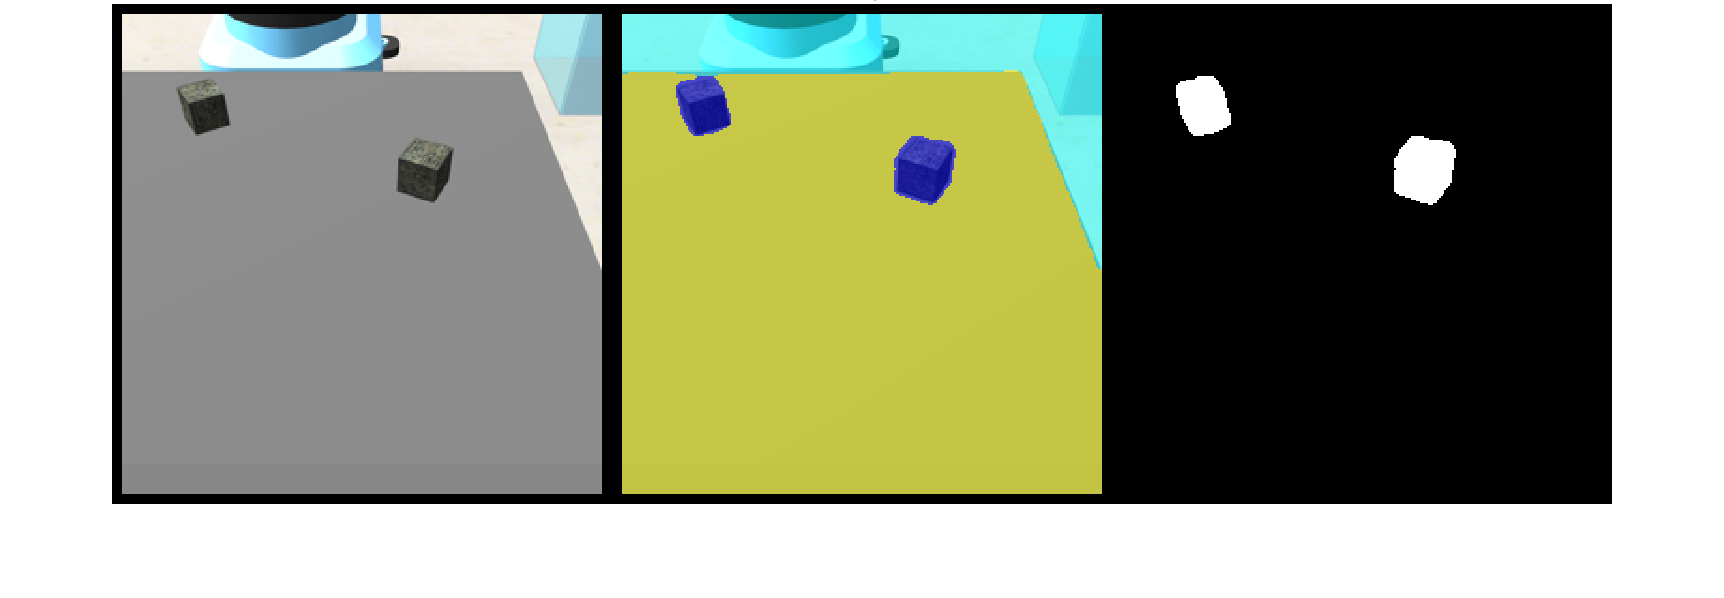

QI = read(PPtest);
QP = QI{1};
QC = semanticseg(QP,DCNN);
QB = labeloverlay(QP,QC);
QM = QC == 'cube';
montage({QP,QB,QM},'BorderSize',10,"Size",[1 3]); title('Predicted Segmentation')

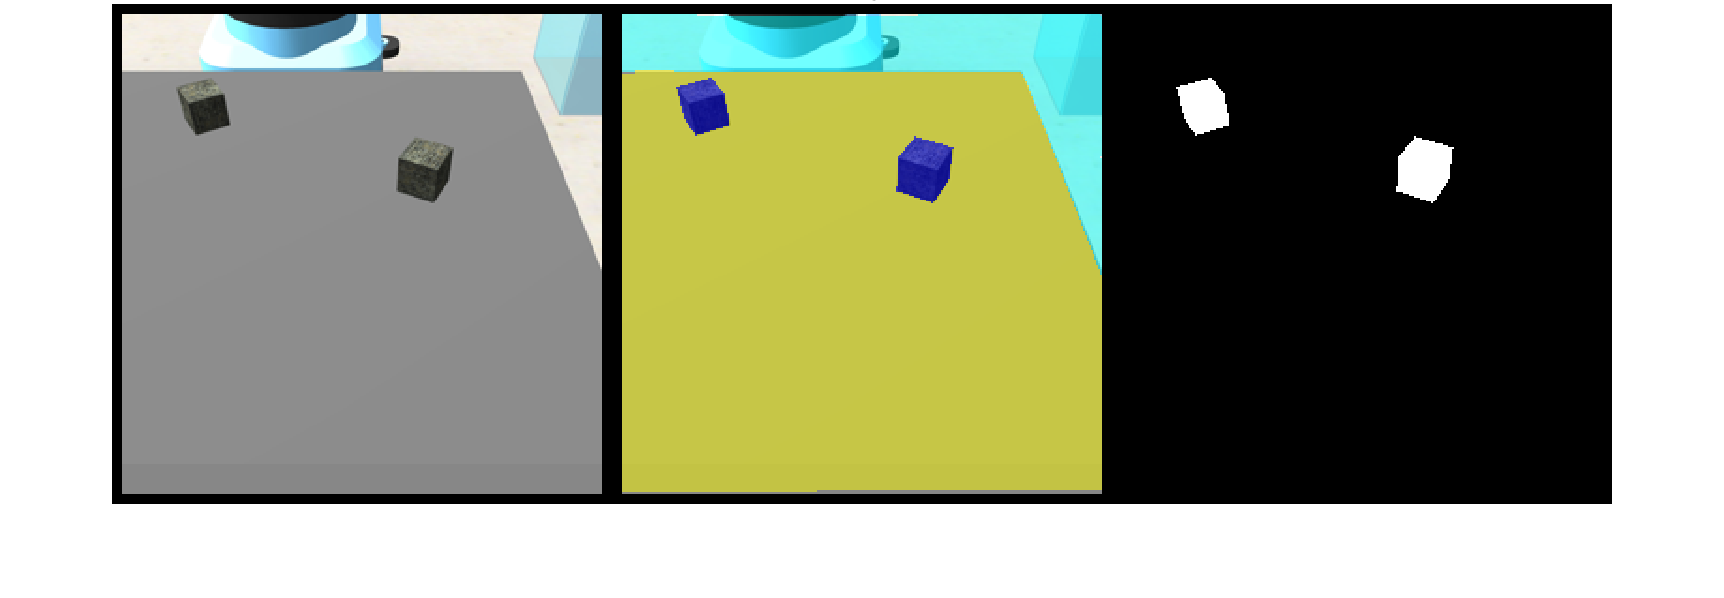

expR = QI{2};
exp = uint8(expR);
acc = uint8(QC);
QCE = labeloverlay(QP,expR);
QME = expR == 'cube';
montage({QP,QCE,QME},'BorderSize',10,"Size",[1 3]); title('Expected Segmentation')

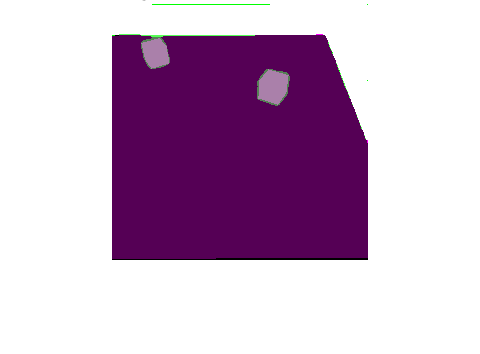

imshowpair(acc, exp); title('gTruth Comparison')

iou = jaccard(QC,expR);
table(classes,iou)

ans = 3×2 table
       classes               iou       
    ______________    _________________

    {'Belt'      }    0.983424492444609
    {'cube'      }    0.829034193161368
    {'Background'}    0.969086021505376


## Evaluate Prediction Quality

TestI = transform(imdsTest,@(data)imresize(data,inputSize(1:2)));
pxdsPred = semanticseg(TestI,DCNN,'MiniBatchSize',5,'WriteLocation',temp);

Running semantic segmentation network
-------------------------------------
* Processed 16 images.



TestL = transform(pxdsTest,@(data)imresize(data{1},inputSize(1:2),'Method',"nearest"));
metrics = evaluateSemanticSegmentation(pxdsPred,TestL);

Evaluating semantic segmentation results
----------------------------------------
* Selected metrics: global accuracy, class accuracy, IoU, weighted IoU, BF score.
* Processed 16 images.
* Finalizing... Done.
* Data set metrics:

     GlobalAccuracy        MeanAccuracy            MeanIoU            WeightedIoU          MeanBFScore   
    _________________    _________________    _________________    _________________    _________________

    0.992564769556937    0.996604852306809    0.941952354281341    0.985873128746323    0.985110834380493



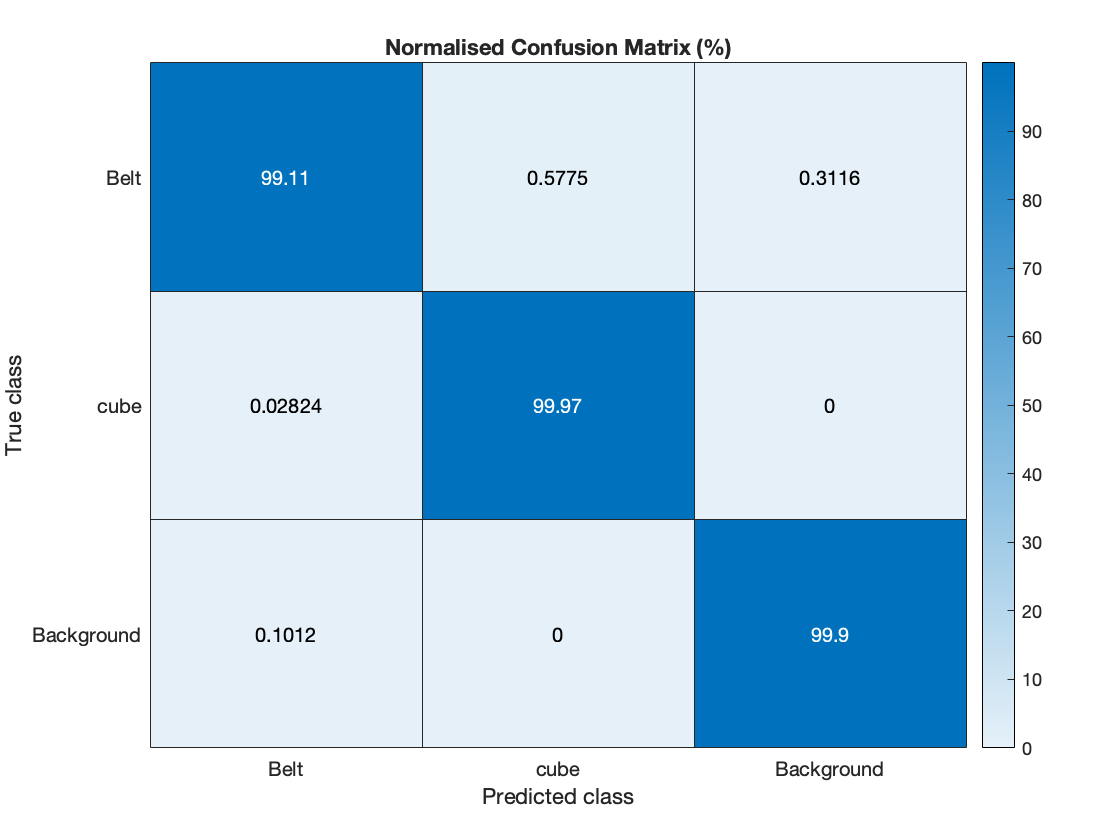

normConfMat = metrics.NormalizedConfusionMatrix.Variables;
figure
h = heatmap(classes,classes,100*normConfMat);
h.XLabel = 'Predicted class';
h.YLabel = 'True class';
h.Title = 'Normalised Confusion Matrix (%)';

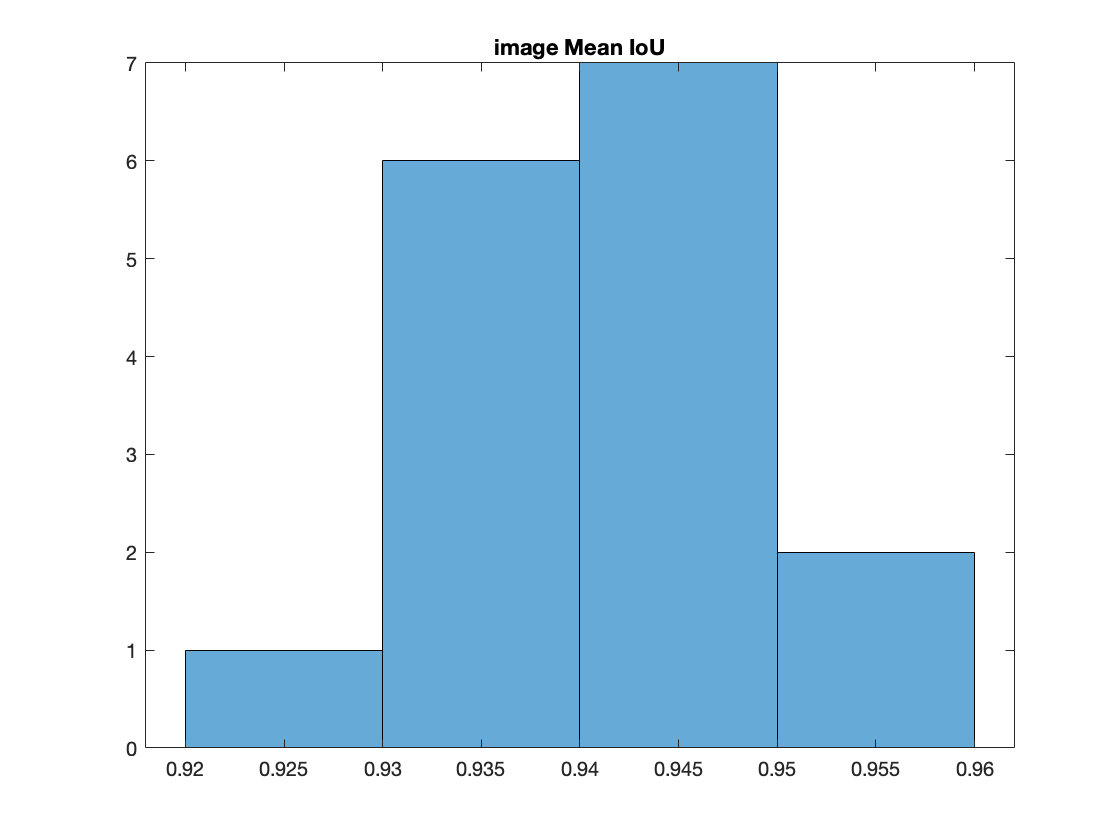

imageIoU = metrics.ImageMetrics.MeanIoU;
figure
histogram(imageIoU)
title('image Mean IoU')

metrics.ClassMetrics

ans = 3×3 table
                      Accuracy                IoU              MeanBFScore   
                  _________________    _________________    _________________

    Belt          0.991109264840349    0.990909861024176    0.990838460110607
    cube          0.999717613836922    0.852122634413455    0.966099345099161
    Background    0.998987678243156    0.982824567406394    0.998394697931711
